syms alpha theta t
assume([alpha, theta, t], 'real')

% Axis of rotation as a function of time
alpha = [
    1;
    0;
    0;
];
% Angle of rotation as a function of time
theta = 0.2*t;

% Construct the quaternion using axis-angle
q_t = [
    cos(theta/2);
    sin(theta/2)*alpha;
];

%q_t = q_t / norm(q_t);

r_t = [
    0;
    t;
    0;
];

g_t = construct_pose(q_t, r_t);
g_dot = simplify(diff(g_t));
g_inv = simplify(construct_pose(invert_quat(q_t), -r_t));
g_circ_right = simplify(g_inv*g_dot)

$$g\_circ\_right = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & \frac{1}{5} & \cos\left(\frac{t}{5}\right)\\ 0 & -\frac{1}{5} & 0 & \sin\left(\frac{t}{5}\right)\\ 0 & 0 & 0 & 0 \end{array}\right)$$

omega = [g_circ_right(2, 1); -g_circ_right(3, 1); g_circ_right(3, 2)];
v = g_circ_right(1:3, 4);
a = simplify(diff(v));

n = 348;
tspan = linspace(0, 10, n);
r_vals = eval(subs(r_t, t, tspan))';
q_vals = eval(subs(q_t, t, tspan))';

figure()
hold on

% Calculate indices to show the transform frames
% Finds all factors of the total index number, and picks the factor closest
% to a desired number of frames to show. This way we ensure that the frames
% are always evenly distributed, at the cost of sometimes showing more/less
% than the desired number of frames.
ideal_frame_numb = 15;
indices = 1:n;
all_factors = indices(rem(n, indices) == 0);
[~, i] = min(abs(all_factors - ideal_frame_numb));
indices_tform = linspace(0, n, all_factors(i)+1);
indices_tform(1) = 1;
fprintf("Final transform number: %d", all_factors(i)+1)

Final transform number: 13

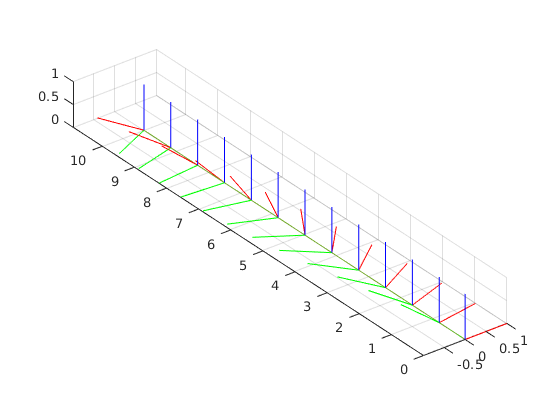


plotTransforms(r_vals(indices_tform, :), q_vals(indices_tform, :))
plot3(r_vals(:, 1), r_vals(:, 2), r_vals(:, 3))
axis equal
grid on

function mat = quat_vec_to_mat(q)
    % Reurnts the corresponding rotation matrix for a quaterion q, in
    % homogenous coordinates
    [w, x, y, z] = deal(q(1), q(2), q(3), q(4));
    
    % Formula from http://groups.csail.mit.edu/graphics/classes/6.837/F01/Lecture09/Slide24.html
    mat = [
       1-2*y^2-2*z^2, 2*x*y+2*w*z,   2*x*z-2*w*y,   0;
       2*x*y-2*w*z,   1-2*x^2-2*z^2, 2*y*z+2*w*x,   0;
       2*x*z+2*w*y,   2*y*z-2*w*x,   1-2*x^2-2*y^2, 0;
       0,             0,             0,             1;
    ];
end

function pose_out = construct_pose(q, r)
    pose_out = sym(quat_vec_to_mat(q));
    pose_out(1:3, 4) = r;
end

function q_out = invert_quat(q)
    q_out = q;
    q_out(2:4) = -q(2:4);
end

function q_out = canonicalize_quat(q)
    q_out = q;
    if q_out(1) < 0
        q_out = -q_out;
    end
end